# Projection Two-Photon Lithography Simulation Toolbox for MATLAB (OS-FDM 2D)

This live script demonstates how to conduct a 2D P-TPL simulation simulation using the operator splitting finite difference method (OS-FDM). Some of the function calls in this script can take several minutes to return. You can use the Run Section button to run one section at a time if more convenient.

## Defining System Parameters and DMD image

First, define your system parameters using [make_system_profile.m](matlab:open('./make_system_profile.m')). Enter a system name and edit the parameter values as needed. Sample parameter file for the authors' P-TPL printing system at [Georgia Tech](matlab:open('./STEAM_Lab_GT.mat')) is included.

Second, create a double array representing the DMD projection. This array should contain 0s where DMD pixels are switched off and 1 where they are switched on. The array should be size *N* x *N, *where *N *must be a power of 2. *N *is 256 by default; if you use a different value of *N*, you must pass this value to [optical_dosage.m](matlab:open('./optical_dosage.m')) when you call it later. For example:

N = 256;
H_dmd = zeros(N);
i_lines = 5;    % simulation of 5 lines
i_width=5;      % of 5 px width
i_period=30;    % and at 30 px period
i_center=floor(i_lines/2)*i_period + ceil(i_width/2);
dmd_pattern=meshgrid(1*(mod((1:i_lines*i_period)-1, i_period)<i_width));
H_dmd(N/2-i_center+1: N/2-i_center + size(dmd_pattern,1), N/2-i_center+1: N/2-i_center + size(dmd_pattern,1))=dmd_pattern; 

This block of code generates an array H_dmd that represents a projection of five lines of 5px width and 30px period on the DMD. The array can be visualized:

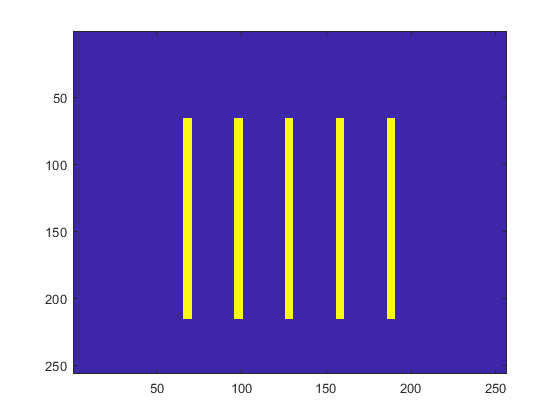

image(H_dmd,"CDataMapping","scaled")

## Simulating System Optics to get Optical Dosage

Next, call [optical_dosage.m](matlab:open('./optical_dosage.m')) to predict what optical dosage and intensity would result from projecting this DMD image. Supply the DMD array and the name of the .mat file containing your system profile, for instance:

(disabled since we will use the next function call instead)

[optical_dosage.m](matlab:open('./optical_dosage.m')) can also be called with optional arguments to override any of the following default parameters:

Optional arguments should be supplied as name-value pairs. For example, to override the default beam power for the STEAM Lab at GT system and instead use a beam power of 100 nW/pixel, while also producing a plot, we can call:

[I_fz,D_fz,Xf,Yf,zf] = optical_dosage(H_dmd, 'STEAM_Lab_GT.mat', 'calibration_power',100e-9,'make_plot',true);

'optical_dosage' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\ssaha8\GaTech Dropbox\Sourabh Saha\Work\Research\Research projects\TPL simulations\GT simulations\Optics\PTPL Simulation Toolbox V2
    C:\Users\ssaha8\GaTech Dropbox\Sourabh Saha\Work\Research\Research projects\TPL simulations\GT simulations\Optics\PTPL Simulation Toolbox V2\Codes for VIP class
    C:\Users\ssaha8\Dropbox (GaTech)\Work\Research\Research projects\TPL simulations\GT simulations\Optics\PTPL Simulation Toolbox V2
    C:\Users\ssaha8\Dropbox (GaTech)\Work\STEAM Group\Student Files\STEAM_RP_2020\PTPL Simulation Toolbox

Change the MATLAB current folder or add its folder to the MATLAB path.

## Simulating Reaction and Diffusion to get Degree of Conversion

Having obtained the optical dosage at each coordinate in 3D space during a laser pulse, we can now simulate the polymerization chemistry that constitutes the remainder of P-TPL printing.

First, conduct a 2D simulation of the centermost *xz* plane. To do this, first extract the values of dosage in that plane and generate coordinate arrays that correspond to it:

D_xz=squeeze(D_fz(N/2+1,:,:))';
[coordx_2D, coordz_2D]=meshgrid(Xf(1,:,1),zf);

Now call [fdm_2D.m](matlab:open('./fdm_2D.m')) to perform a 2D reaction-diffusion simulation:

[X_2D,Z_2D,DOC_2D] = fdm_2D(D_xz,coordx_2D,coordz_2D);

Once again, optional arguments can be supplied to override any of the following default parameters:

For instance, to perform a simulation of 5 pulses and generate a plot:

[X_2D,Z_2D,DOC_2D] = fdm_2D(D_xz,coordx_2D,coordz_2D,'pulse_count',5,'make_plot',true);

[](matlab:open('./fdm_3D.m'))